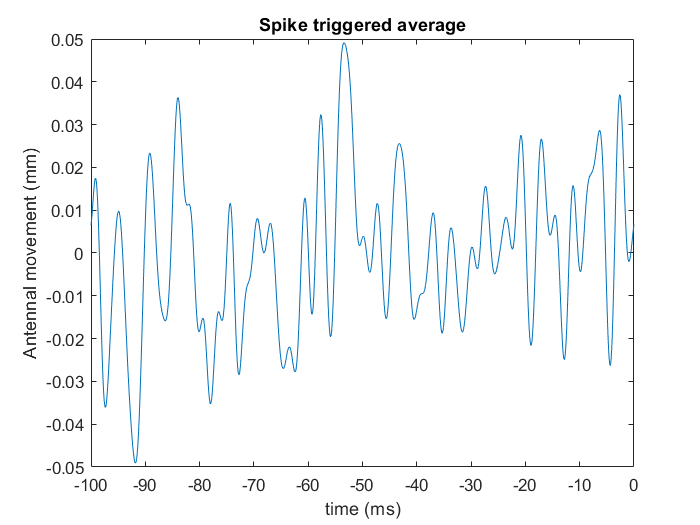

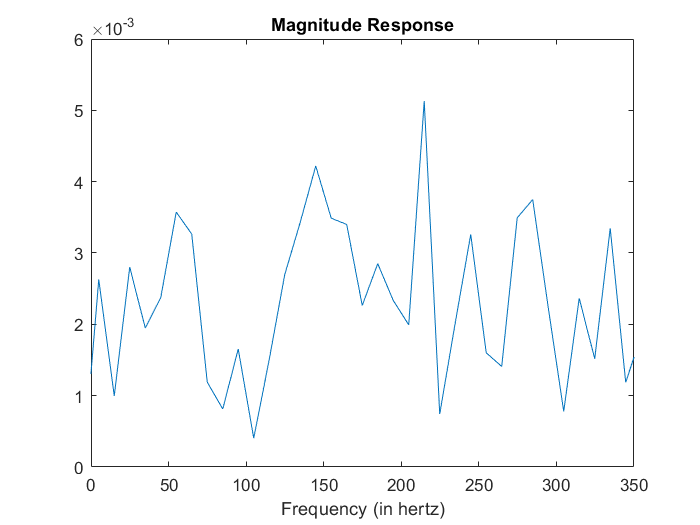


STA_freq =

     []



power_fft =   -0.0006 + 0.0061i  -0.0006 + 0.0061i  -0.0007 + 0.0061i  -0.0007 + 0.0061i  -0.0007 + 0.0061i  -0.0007 + 0.0061i  -0.0007 + 0.0061i  -0.0008 + 0.0061i  -0.0008 + 0.0061i  -0.0008 + 0.0061i  -0.0008 + 0.0061i  -0.0008 + 0.0061i  -0.0008 + 0.0061i  -0.0009 + 0.0061i  -0.0009 + 0.0061i  -0.0009 + 0.0061i  -0.0009 + 0.0061i  -0.0009 + 0.0061i  -0.0010 + 0.0061i  -0.0010 + 0.0061i  -0.0010 + 0.0061i  -0.0010 + 0.0061i  -0.0010 + 0.0061i  -0.0010 + 0.0061i  -0.0011 + 0.0061i  -0.0011 + 0.0061i  -0.0011 + 0.0061i  -0.0011 + 0.0061i  -0.0011 + 0.0061i  -0.0012 + 0.0061i  -0.0012 + 0.0061i  -0.0012 + 0.0061i  -0.0012 + 0.0061i  -0.0012 + 0.0061i  -0.0013 + 0.0061i  -0.0013 + 0.0061i  -0.0013 + 0.0061i  -0.0013 + 0.0061i  -0.0013 + 0.0061i  -0.0013 + 0.0061i  -0.0014 + 0.0061i  -0.0014 + 0.0061i  -0.0014 + 0.0061i  -0.0014 + 0.0061i  -0.0014 + 0.0061i  -0.0015 + 0.0061i  -0.0015 + 0.0061i  -0.0015 + 0.0061i  -0.0015 + 0.0061i  -0.0015 + 0.0061i


frq_fft = 	1.0e+03 *

   -5.0000   -4.9900   -4.9800   -4.9700   -4.9600   -4.9500   -4.9401   -4.9301   -4.9201   -4.9101   -4.9001   -4.8901   -4.8801   -4.8701   -4.8601   -4.8501   -4.8402   -4.8302   -4.8202   -4.8102   -4.8002   -4.7902   -4.7802   -4.7702   -4.7602   -4.7502   -4.7403   -4.7303   -4.7203   -4.7103   -4.7003   -4.6903   -4.6803   -4.6703   -4.6603   -4.6503   -4.6404   -4.6304   -4.6204   -4.6104   -4.6004   -4.5904   -4.5804   -4.5704   -4.5604   -4.5504   -4.5405   -4.5305   -4.5205   -4.5105


STA =    0.0065 - 0.0019i   0.0077 - 0.0003i   0.0092 + 0.0011i   0.0109 + 0.0023i   0.0127 + 0.0034i   0.0144 + 0.0042i   0.0159 + 0.0048i   0.0169 + 0.0052i   0.0174 + 0.0053i   0.0173 + 0.0051i   0.0165 + 0.0047i   0.0149 + 0.0041i   0.0125 + 0.0032i   0.0095 + 0.0022i   0.0058 + 0.0009i   0.0016 - 0.0006i  -0.0030 - 0.0021i  -0.0078 - 0.0038i  -0.0126 - 0.0055i  -0.0173 - 0.0073i  -0.0217 - 0.0091i  -0.0257 - 0.0108i  -0.0291 - 0.0125i  -0.0319 - 0.0141i  -0.0340 - 0.0156i  -0.0354 - 0.0170i  -0.0360 - 0.0182i  -0.0360 - 0.0193i  -0.0354 - 0.0202i  -0.0343 - 0.0211i  -0.0326 - 0.0217i  -0.0307 - 0.0223i  -0.0284 - 0.0228i  -0.0259 - 0.0231i  -0.0234 - 0.0234i  -0.0207 - 0.0235i  -0.0180 - 0.0236i  -0.0153 - 0.0236i  -0.0126 - 0.0236i  -0.0099 - 0.0234i  -0.0074 - 0.0231i  -0.0049 - 0.0227i  -0.0025 - 0.0222i  -0.0002 - 0.0215i   0.0019 - 0.0207i   0.0039 - 0.0197i   0.0056 - 0.0185i   0.0071 - 0.0171i   0.0083 - 0.0156i   0.0092 - 0.0138i


rand_stim = rand([1,10000]);
rand_stim = butter_filtfilt(rand_stim, 300, 10000, 4);

rand_raster = zeros([1,10000]);
rand_locs = randi(10000, [1,4000]);
rand_raster(rand_locs) = 1;

[STA_freq, power_fft, frq_fft,STA] = STA_analysis(rand_raster, rand_stim, 0.1, 10000)